a = 1 + mod(137,3)

a = 3

%Q1)
%1)
figure;
t = 0:0.001:2;
n = 0:119;
fs = 120;
x = 1*sin(2*pi*15*a*n/fs);
z = fft(x)

z =    0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 -60.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i


% f = (0:length(y)-1)*100/length(y);
f = (0:119)*fs/120 

f =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


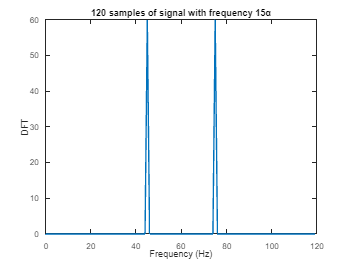

plot(f,abs(z))
xlabel('Frequency (Hz)')
ylabel('DFT')
title('120 samples of signal with frequency 15α')

% No spectral leakage

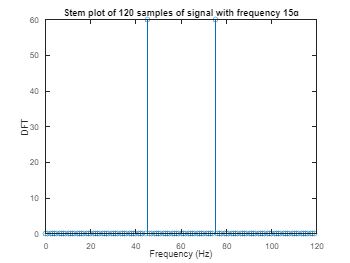

stem(f,abs(z))
xlabel('Frequency (Hz)')
ylabel('DFT')
title('Stem plot of 120 samples of signal with frequency 15α')

%2)
n2 = 0:129;
x2 = 1*sin(2*pi*15*a*n2/fs);
z2 = fft(x2)

z2 =    0.7071 + 0.0000i   0.7072 + 0.0142i   0.7077 + 0.0283i   0.7084 + 0.0426i   0.7094 + 0.0569i   0.7107 + 0.0713i   0.7123 + 0.0859i   0.7142 + 0.1006i   0.7165 + 0.1154i   0.7191 + 0.1305i   0.7220 + 0.1459i   0.7253 + 0.1615i   0.7290 + 0.1775i   0.7332 + 0.1938i   0.7378 + 0.2106i   0.7429 + 0.2278i   0.7485 + 0.2455i   0.7547 + 0.2638i   0.7615 + 0.2827i   0.7690 + 0.3023i   0.7773 + 0.3227i   0.7863 + 0.3440i   0.7963 + 0.3663i   0.8074 + 0.3896i   0.8195 + 0.4143i   0.8330 + 0.4403i   0.8479 + 0.4680i   0.8646 + 0.4975i   0.8831 + 0.5290i   0.9038 + 0.5630i   0.9272 + 0.5997i   0.9535 + 0.6397i   0.9835 + 0.6835i   1.0177 + 0.7319i   1.0571 + 0.7857i   1.1027 + 0.8462i   1.1562 + 0.9148i   1.2196 + 0.9937i   1.2956 + 1.0856i   1.3881 + 1.1945i   1.5030 + 1.3263i   1.6489 + 1.4895i   1.8396 + 1.6983i   2.0989 + 1.9762i   2.4700 + 2.3666i   3.0428 + 2.9595i   4.0375 + 3.9751i   6.1782 + 6.1376i  14.0508 +14.0330i -41.1328 -41.1267i


% f = (0:length(y)-1)*100/length(y);
f2 = (0:129)*fs/130 

f2 =          0    0.9231    1.8462    2.7692    3.6923    4.6154    5.5385    6.4615    7.3846    8.3077    9.2308   10.1538   11.0769   12.0000   12.9231   13.8462   14.7692   15.6923   16.6154   17.5385   18.4615   19.3846   20.3077   21.2308   22.1538   23.0769   24.0000   24.9231   25.8462   26.7692   27.6923   28.6154   29.5385   30.4615   31.3846   32.3077   33.2308   34.1538   35.0769   36.0000   36.9231   37.8462   38.7692   39.6923   40.6154   41.5385   42.4615   43.3846   44.3077   45.2308


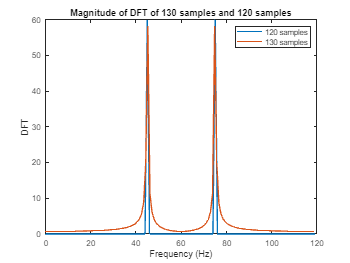

plot(f,abs(z),f2,abs(z2))
legend('120 samples','130 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')
title('Magnitude of DFT of 130 samples and 120 samples')

% Spectral leakage is observed.

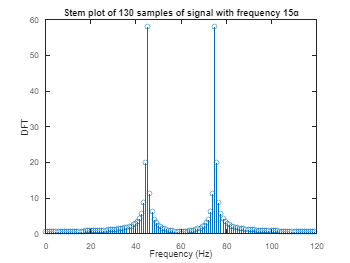

stem(f2,abs(z2))
xlabel('Frequency (Hz)')
ylabel('DFT')
title('Stem plot of 130 samples of signal with frequency 15α')

%3) N = 120/15a multiples itself ie 120/45
figure();
subplot(2,2,1);
n3 = 0:239;
x3 = 1*sin(2*pi*15*a*n3/fs);
z3 = fft(x3);
% f = (0:length(y)-1)*100/length(y);
f3 = n3*fs/length(n3)

f3 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000


stem(f3,abs(z3))
title('N = 240')
xlabel('Frequency (Hz)')
ylabel('DFT')
subplot(2,2,2);
n3 = 0:359;
x3 = 1*sin(2*pi*15*a*n3/fs);
z3 = fft(x3);
% f = (0:length(y)-1)*100/length(y);
f3 = n3*fs/600;
stem(f3,abs(z3))
title('N = 360')
xlabel('Frequency (Hz)')
ylabel('DFT')
subplot(2,2,3);
n3 = 0:479;
x3 = 1*sin(2*pi*15*a*n3/fs);
z3 = fft(x3)

z3 = 1.0e+02 *

  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i


% f = (0:length(y)-1)*100/length(y);
f3 = n3*fs/600 

f3 =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


stem(f3,abs(z3))
title('N = 480')
xlabel('Frequency (Hz)')
ylabel('DFT')
subplot(2,2,4);
n3 = 0:599;
x3 = 1*sin(2*pi*15*a*n3/fs);
z3 = fft(x3)

z3 = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i


% f = (0:length(y)-1)*100/length(y);
f3 = n3*fs/600 

f3 =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


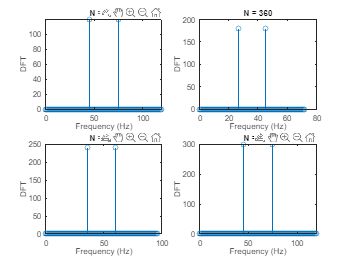

stem(f3,abs(z3))
title('N = 600')
xlabel('Frequency (Hz)')
ylabel('DFT')

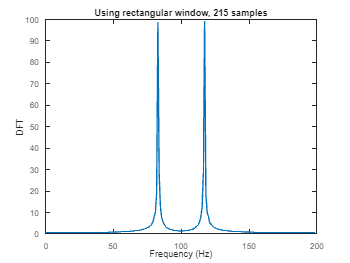

%Q2)
figure;
A = 160;
B = 166;
fs =200;
t = 0:1/fs:10-1/fs;
X2 = 0.1*sin(A*pi*t) + cos(B*pi*t);

N = 0:214;
z4 = fft(X2,length(N));
% X_dash = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs)
% z4_dash = fft(X_dash)
F = N*fs/length(N);
plot(F,abs(z4))
title('Using rectangular window, 215 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

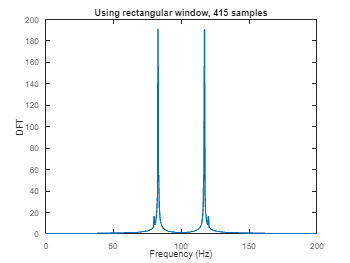

N = 0:414;
z4 = fft(X2,length(N));
% X_dash = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs)
% z4_dash = fft(X_dash)
F = N*fs/length(N);
plot(F,abs(z4))
title('Using rectangular window, 415 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

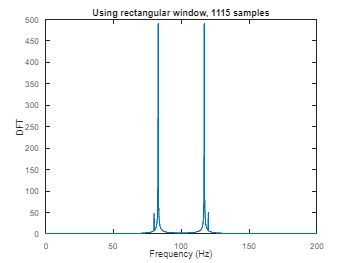

N = 0:1114;
z4 = fft(X2,length(N));
% X_dash = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs)
% z4_dash = fft(X_dash)
F = N*fs/length(N);
plot(F,abs(z4))
title('Using rectangular window, 1115 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

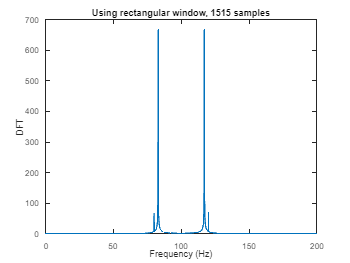

N = 0:1514;
z4 = fft(X2,length(N));
% X_dash = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs)
% z4_dash = fft(X_dash)
F = N*fs/length(N);
plot(F,abs(z4))
title('Using rectangular window, 1515 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

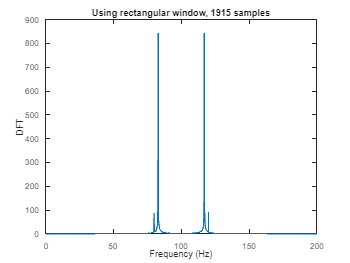

N = 0:1914;
z4 = fft(X2,length(N));
% X_dash = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs)
% z4_dash = fft(X_dash)
F = N*fs/length(N);
plot(F,abs(z4))
title('Using rectangular window, 1915 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

%Collect more samples so that resolution increases.

%Q3)
figure;
N = 0:214;
X2 = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs)

X2 =     1.0000   -0.8020    0.3866    0.1265   -0.5946    0.8910   -0.9392    0.7320   -0.3307   -0.1529    0.5878   -0.8590    0.8970   -0.6950    0.3093    0.1564   -0.5786    0.8458   -0.8872    0.6913   -0.3090   -0.1594    0.5894   -0.8652    0.9098   -0.7071    0.3075    0.1839   -0.6339    0.9171   -0.9511    0.7201   -0.2825   -0.2436    0.7117   -0.9877    0.9886   -0.7080    0.2204    0.3384   -0.8090    1.0543   -0.9999    0.6572   -0.1216   -0.4540    0.9031   -1.0946    0.9714   -0.5678


w = blackman(length(N));
Y2 = X2.*transpose(w)

Y2 =          0   -0.0001    0.0001    0.0001   -0.0007    0.0017   -0.0027    0.0028   -0.0017   -0.0010    0.0047   -0.0084    0.0105   -0.0096    0.0050    0.0029   -0.0124    0.0206   -0.0244    0.0214   -0.0107   -0.0061    0.0252   -0.0408    0.0473   -0.0403    0.0191    0.0125   -0.0468    0.0734   -0.0823    0.0673   -0.0284   -0.0264    0.0826   -0.1228    0.1314   -0.1004    0.0333    0.0544   -0.1382    0.1910   -0.1919    0.1334   -0.0261   -0.1027    0.2153   -0.2747    0.2562   -0.1572


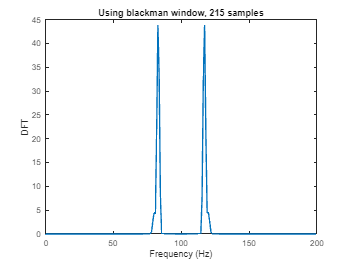

z4 = fft(Y2,length(N));
F = N*fs/length(N);
plot(F,abs(z4))
title('Using blackman window, 215 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

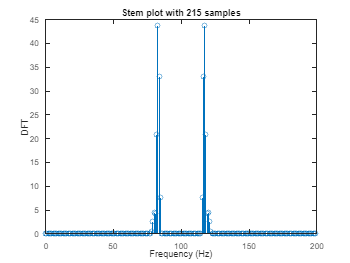

stem(F,abs(z4))
title('Stem plot with 215 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

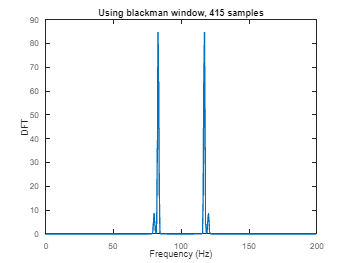

N = 0:414;
X2 = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs);
w = blackman(length(N));
Y2 = X2.*transpose(w);
z4 = fft(Y2,length(N));
F = N*fs/length(N);
plot(F,abs(z4))
title('Using blackman window, 415 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

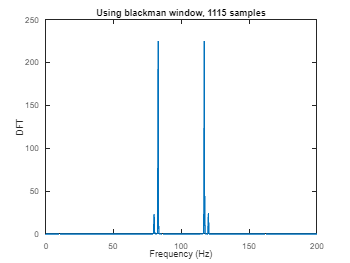

N = 0:1114;
X2 = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs);
w = blackman(length(N));
Y2 = X2.*transpose(w);
z4 = fft(Y2,length(N));
F = N*fs/length(N);
plot(F,abs(z4))
title('Using blackman window, 1115 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

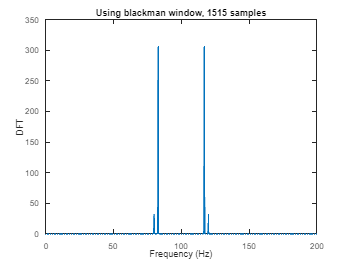

N = 0:1514;
X2 = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs);
w = blackman(length(N));
Y2 = X2.*transpose(w);
z4 = fft(Y2,length(N));
F = N*fs/length(N);
plot(F,abs(z4))
title('Using blackman window, 1515 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

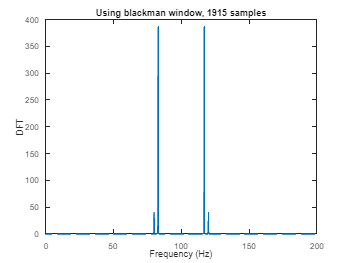

N = 0:1914;
X2 = 0.1*sin(A*pi*N/fs) + cos(B*pi*N/fs);
w = blackman(length(N));
Y2 = X2.*transpose(w);
z4 = fft(Y2,length(N));
F = N*fs/length(N);
plot(F,abs(z4))
title('Using blackman window, 1915 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

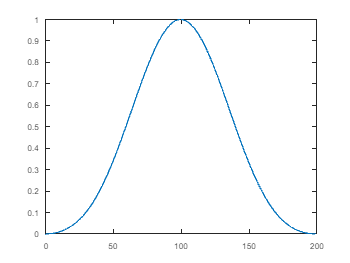

plot(F,w)

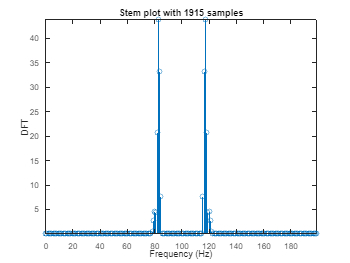

stem(F,abs(z4))
title('Stem plot with 1915 samples')
xlabel('Frequency (Hz)')
ylabel('DFT')

% Comparing with the 2nd problem, we notice that the spectral leakage has
% been visibly reduced by using a blackman window but only with a trade-off
% with resolution decreasing

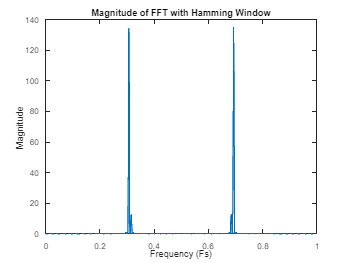

%Q4
data = load('Exp4Data3.txt');
Fs = 1; 
T=1/Fs;
t=0:T:duration-T;
N = length(data);

%q4(a)
window = hamming(N);
data_window = data .* window';

n= 10000;
fft_new = fft(data_window, n);
freq = (0:n-1) * (Fs / n);
freq_normalized = freq;
figure;
plot(freq_normalized, abs(fft_new));
title('Magnitude of FFT with Hamming Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_new), 2);
frequencies = freq_normalized(max_indices);
disp(['Estimated Frequencies using Hamming Window: ', num2str(sort(frequencies))]);

Estimated Frequencies using Hamming Window: 0.307       0.693


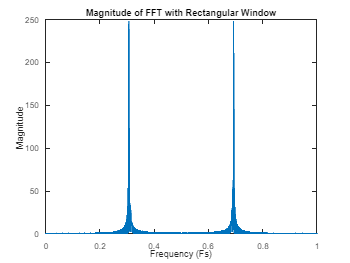


%q4(b)
window_rect = rectwin(N);
data_window_rect = data .* window_rect';
fft_rect = fft(data_window_rect, n);
figure;
plot(freq_normalized, abs(fft_rect));
title('Magnitude of FFT with Rectangular Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_rect), 2);
frequencies1 = freq_normalized(max_indices);
disp(['Estimated Frequencies using Rectangular Window: ', num2str(sort(frequencies1))]);

Estimated Frequencies using Rectangular Window: 0.307       0.693
